## EL2

#### P1)

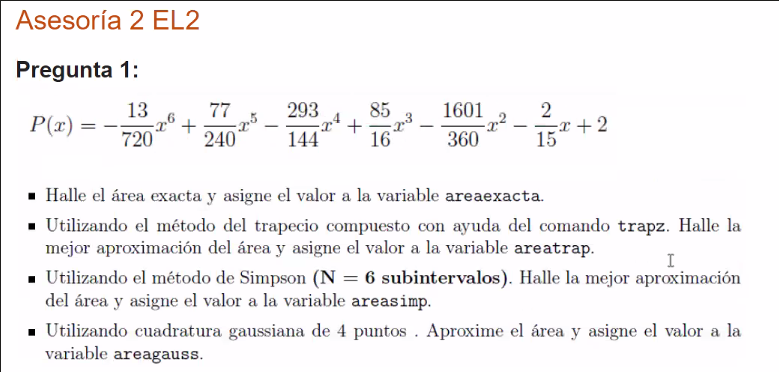

syms x
f = (-13/720)*x^6 + (77/240)*x^5 - (293/144)*x^4 + (85/16)*x^3 - (1601/360)*x^2 - (2/15)*x + 2;

areaexacta = double(int(f,x,[0 6]))

areaexacta =   18.992857142857144



x = [0 1 2 3 4 5 6];
y = [2 1 3 5 4 3 4];

areatrap = trapz(x,y)

areatrap =     19


areasimp = Simpcomp(matlabFunction(f),0,6,6)

areasimp =   18.666666666666888


areagauss = gaussnp(matlabFunction(f),0,6,6)

areagauss =   18.992857142857215


#### P2)

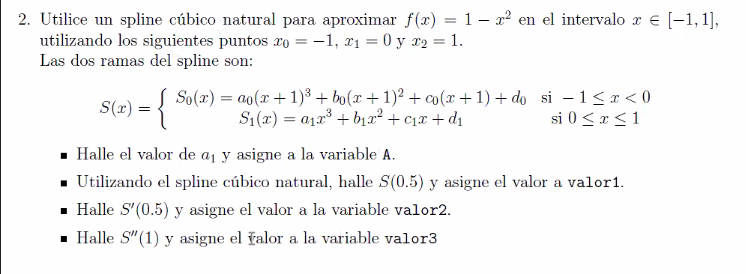

f = @(x) 1 - x.^2

f = function_handle with value:
    @(x)1-x.^2



x = [-1 0 1]

x =     -1     0     1


y = f(x)

y =      0     1     0


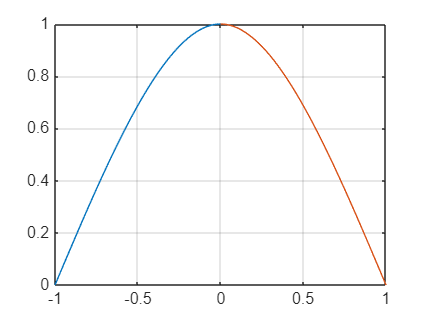

S =   -0.500000000000000                   0   1.500000000000000                   0
   0.500000000000000  -1.500000000000000                   0   1.000000000000000



S = splinenatural(x,y)


A = p(2,1)

A =    0.500000000000000



S0 = @(x) S(1,1)*(x+1)^3 + S(1,2)*(x+1)^2 + S(1,3)*(x+1) + S(1,4);
S1 = @(x) S(2,1)*(x-0)^3 + S(2,2)*(x-0)^2 + S(2,3)*(x-0) + S(2,4);

valor1 = S0(0.5)

valor1 =    0.562500000000000



syms x

dS1 = diff(S1,x);
valor2 = double(subs(dS1,x,0.5))

valor2 =   -1.125000000000000



d2S1 = diff(dS1,x);
valor3 = double(subs(d2S1,x,1))

valor3 =      0


#### P3)

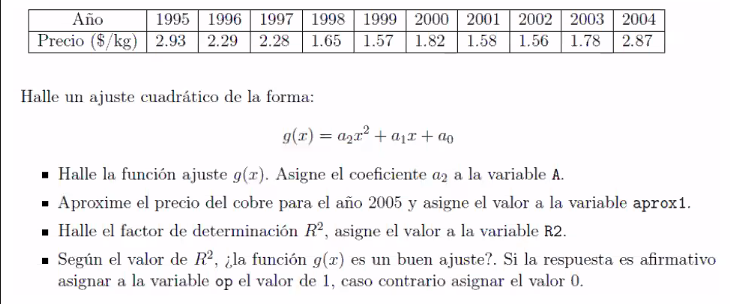

x = [1 2 3 4 5 6 7 8 9 10];
y = [2.93 2.29 2.28 1.65 1.57 1.82 1.58 1.56 1.78 2.87];

g = polyfit(x,y,2)

g =    0.060037878787879  -0.706901515151515   3.609499999999998


A = g(1,1);

aprox1 = polyval(g,11)

aprox1 =    3.098166666666664



aproxvals = polyval(g,x);
R2 = 1 - sum((y-aproxvals).^2)/sum((y-mean(y)).^2)

R2 =    0.822192261649761



op = 1

op =      1


#### P4)

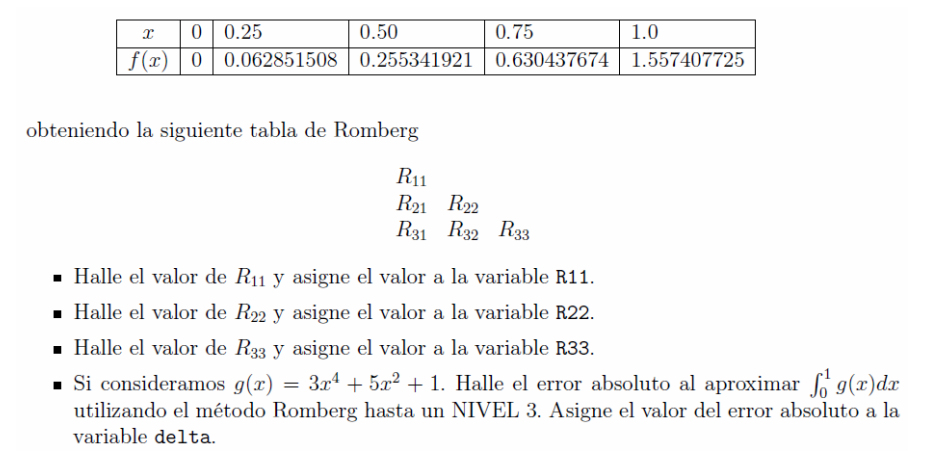

#### Funciones

function I=Simpcomp(f,a,b,n)
h=(b-a)/n;
x=a:h:b;
xpar=x(2:2:length(x)-1);
ximpar=x(3:2:length(x)-2);
I=(h/3)*(f(a)+4*sum(f(xpar))+2*sum(f(ximpar))+f(b));
end

function G=gaussnp(f,a,b,n)
syms x
%PRIMER PASO: Calcular el polinomio de Legendre de grado n
lg=legendreP(n,x);
dlg=matlabFunction(diff(lg,x));
%SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
roots=double(vpasolve(lg==0));
%TERCER PASO: Calcular los pesos de las raíces del polinomio de Legendre
pesos=(2./((1-roots.^2).*dlg(roots).^2));
%CUARTO PASO: Transformar los límites de la fxn
syms t
x=((b-a)*t+(a+b))/2;
F=matlabFunction(f(x));
%QUINTO PASO: Calcular el valor de la integral
G=((b-a)/2)*sum(pesos.*(F(roots)));
end

function S=splinenatural(X,Y)
N=length(X)-1;
H=diff(X);
E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N));
diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E');
g=A\b;
g=[g0 g' gn ];
for i=1:N
S(i,1)=(g(i+1)-g(i))/(6*H(i));
S(i,2)=g(i)/2;
S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
S(i,4)=Y(i);
xx=linspace(X(i),X(i+1),100);
yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
plot(xx,yy)
hold on
end
grid on
hold off
end
